## Week 8 - Time Series Stuff

A very common application in science and engineering is that we have a 'time series' of data (say from a sensor sampling a variable every minute, or hour). The characteristics of that data series are incredibly important, in terms of our understanding of the physical system. So, today, we are just going to talk about ways to analyze time series.

clear all
close all
clc

## Block 1 - Outlier Detection

#### Based on Value

One of the first tasks with time series (or other) data is to identify outlier values. Outliers are 'suspect' data points. It can be very difficult to identify outliers as it is a highly subjective thing. One person might view one data point as an outlier, while another person might think it is okay. And, there might be other data points that are 'agreeable' in terms of both people viewing as bad.

Perhaps the 'easiest' identification method is a simple global criterion on range. In other words if the data are less than some y_min or greater than some y_max, they are tagged as outliers. This method requires that you have some knowledge of acceptable values of your variable.

x=1:1:100;
y=rand(100,1);

Below are slider controls. You can adjust them to set the min and max acceptable values. Then, the figure will update, showing you what you have identified as outlier values.

figure(1);
plot(x,y,'o');
hold on

ymin=0.26

ymin = 0.2600

ymax=0.79

ymax = 0.7900

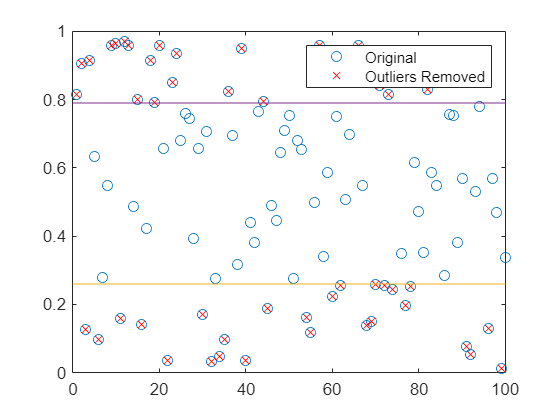


plot(x(y<ymin | y>ymax),y(y<ymin | y>ymax),'rx') %keep only values within limits...
plot([0 100],[ymin ymin]);
plot([0 100],[ymax ymax]);
legend('Original','Outliers Removed')
hold off

#### Based on Variance

Another basis for removing data is based upon the variance of the data, and not absolute limits. For example, we could choose to remove a data point if it was above or below a certain number of standard deviations away from the mean. Let's look at an example below.

load count.dat %there are three columns of positive numbers stored in this file.
mu=mean(count); %computes the mean of each of the columns
sigma=std(count); %computes the standard deviation of the three columns...
figure(1)
plot(count','o'); axis([0 4 0 300])
hold on
plot(mu,'ro','MarkerSize',10,'MarkerFaceColor','red') %plot the means

Below is a slider control. If you set it to 1, then any data point that is more than 1 standard deviation away from the mean will be flagged as an outlier. My code below will also report out the number of outliers per column that you identify.

num_std=2.6

num_std = 2.6000

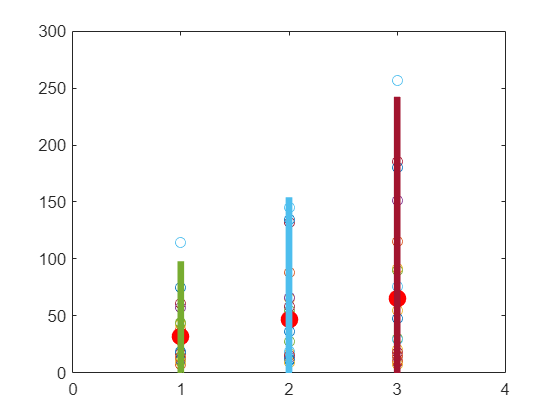

%add bars showing +/- 3 SD
for i=1:3
plot([i i],[mu(i)-num_std*sigma(i) mu(i)+num_std*sigma(i)],'LineWidth',4)
end
hold off


%below, this is just a nifty way of summing up the number of outliers in
%each column...
[n,p]=size(count);
meanmat=repmat(mu,n,1);
sigmamat=repmat(sigma,n,1);
outliers=abs(count-meanmat)>num_std*sigmamat;
number_of_outliers=sum(outliers)

number_of_outliers =      1     0     1


#### Based on Local Neighborhood

The above two methods are 'global' in the sense that they are based upon all of the data. In many ways, it makes far more sense to compare data (for the purposes of outlier detection) to those points 'in the neighborhood.' These methods are local methods, therefore. 

%create some fake data
y=4*sin(linspace(0,2*pi,100));
%add some noise
y=y+0.5*(randn(size(y))-0.5);
%mess with a few points to make them obvious outliers
xbad=randi(100,10,1);
y(xbad)=y(xbad)+(rand(1,10)-.5)*10;

Use the slider controls below to choose (1) the number of points N (to the left and the right) to use in defining the local neighborhood) and (2) the scale factor SF to be used in assessing if a point is an outlier. To be more specific, we will compute the local median (based on the current point and N points to the left and right of the current point). If the current point has a value that is outside the range defined by the median +/- SF*median, we will flag it.

figure(1)
plot(y,'o')

N=8

N = 8

SF=0.7

SF = 0.7000

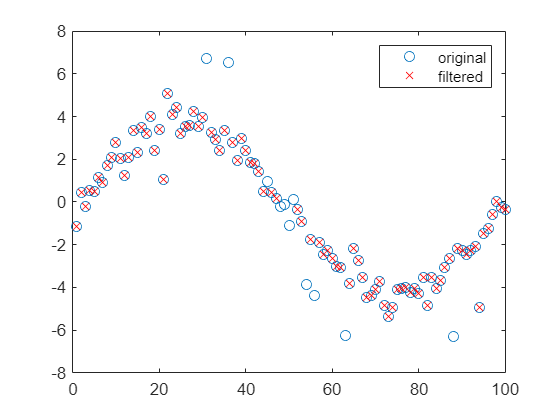

ynew=y;
for j=N+1:1:length(y)-N
    tmp=y(j-N:j+N);
    tmp(N+1)=[]; %so, we exclude the current point. Only include the neighbors
    med=nanmedian(tmp);
    if abs(y(j)-med)>abs(SF*med)
        ynew(j)=NaN;
    end
end
hold on
plot(ynew,'rx')
legend('original','filtered')
hold off

Experiment with the slider controls to see how your choices affect what data points survive. NOTE: you can see that this method does not do well in areas where the data have a value close to zero. In these areas the median of the local neighborhood is close to zero. So, the range of acceptable values becomes very small (a multiple of a very small number) and it looks like we are tossing out plausible data. Just a warning that outlier detction methods have to be very carefully designed.

#### Multivariate data

When we have multivariate data (say pairs of temperature / precipitation data), it can be hard to spot outlier points if we consider the data one variable at a time. So, we have to come up with methods that consider the correlatoin between the data points. Let us start by constructing some correlated bivariate data:

X = mvnrnd([0;0],[1 .9;.9 1],100);

And, let us create four more data points, and store them in a different matrix Y

Y = [1 1;1 -1;-1 1;-1 -1];

Cool, let's now look at the data.

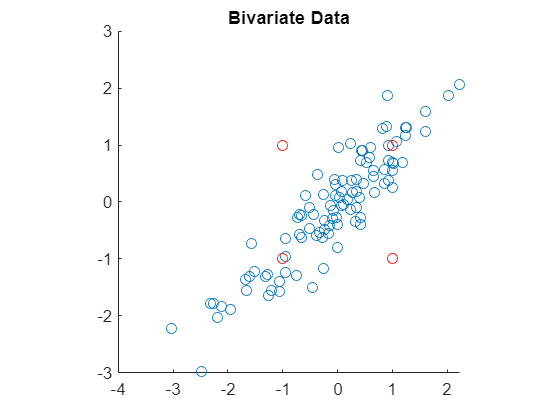

%Make scatter plot:
figure(1)
scatter(X(:,1),X(:,2))
hold on
scatter(Y(:,1),Y(:,2),'r')
hold off
axis square
title('Bivariate Data')

Ok, so two of our Y values seem 'normal' and two seem 'unusual' or possible outliers. BUT, if we just looked at the distribution of the values on either axis independently, the seemingly outlier values would not stand out, i.e. would not be detected as outliers. 

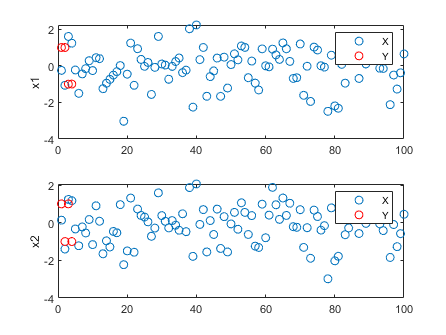

figure(2)
subplot(2,1,1)
plot(X(:,1),'o')
hold on
plot(Y(:,1),'ro')
hold off
ylabel('x1'); legend('X','Y')
subplot(2,1,2)
plot(X(:,2),'o')
hold on
plot(Y(:,2),'ro')
hold off
ylabel('x2'); legend('X','Y')

One way of outlier detection has to do with 'distance'. You can compute the Euclidean distances of the Y points from the mean as below. In the plot, I color the symbols by the distance from the mean of the bivariate data. As you can see, all of the Y points seem 'ok.' They do not stand out when we do this.

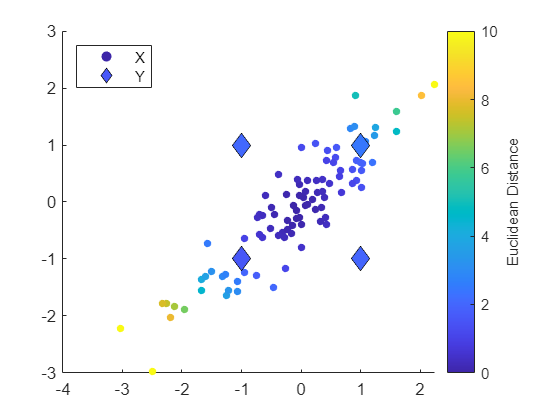

d1 = sum((X-repmat(mean(X),length(X),1)).^2, 2);
d2 = sum((Y-repmat(mean(X),4,1)).^2, 2);
figure(3)
scatter(X(:,1),X(:,2),20,d1,'filled')
hold on
scatter(Y(:,1),Y(:,2),100,d2,'d','filled','MarkerEdgeColor','k')
hb = colorbar;
caxis([0,10])
ylabel(hb,'Euclidean Distance')
legend('X','Y','Location','NW')

So, here is something super neat. We can, instead of using Euclidean distances, compute Mahalanobis distances. Sounds weird, I know. Here is the deal. Instead of using an x,y coordinate system, which is how Euclidean distances are computed, we adopt a new coordinate system that has one axis in the direction (diagonal in this case) of the correlated cloud of data. The other axis is perpendicular to that. And, in those coordinate directions, we recompute standard deviations. In the example above, the standard deviation of the data in the direction of the cloud is large, the standard deviation in the direction perpendicular to that is small. So, for every point on the graph, we can express its position in terms of the number of standard deviations in each of those directions. And, we now compute the distance from the mean in terms of those units, which gives us the Mahalanobis distance. 

This [link](https://www.theinformationlab.co.uk/2017/05/26/mahalanobis-distance/) is actually an extremely good explanation and has very intuitive figures. In the figure below, note that our two suspect points (far from the cloud of data) now clearly stand out.

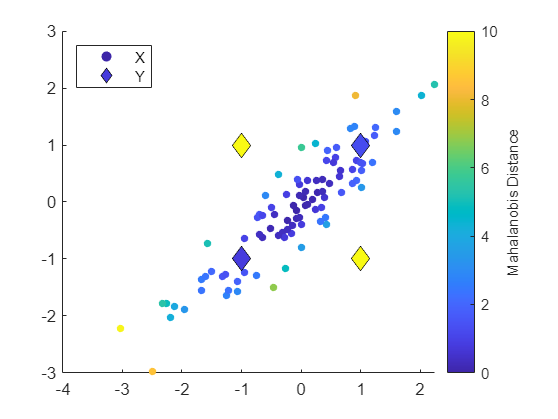

d1 = mahal(Y,X);
figure(4)
scatter(X(:,1),X(:,2),20,mahal(X,X),'filled')
hold on
scatter(Y(:,1),Y(:,2),100,d1,'d','filled','MarkerEdgeColor','k')
hb = colorbar; caxis([0,10])
ylabel(hb,'Mahalanobis Distance')
legend('X','Y','Location','NW')

## Block 2 - Detrending Data

Often time, data will have a particular trend that we might wish to remove prior to carrying out analysis on the data. For example, a sea level rise signal. Or, a climate change signal in temp / precip. There are many ways to do this, based upon the model that YOU select for the background signal. Below, the blue circles are random numbers. I then add a linear trend to these numbers, yielding the red line. Note how the detrend function is able to quite successfully remove the linear trend to recover the original data.

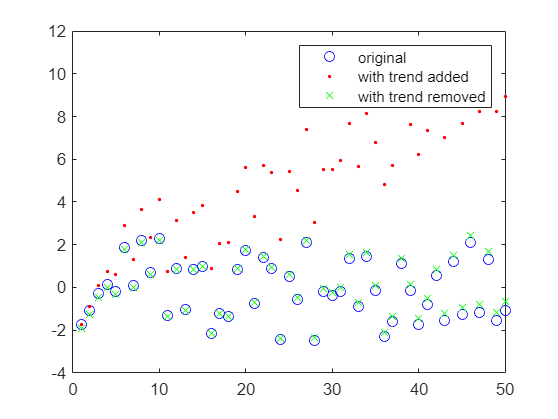

% Matlab's built-in detrend function will do this easily.  

sig = 5*(rand(1,50)-0.5);      % signal with no linear trend
trend = linspace(0,10,50);      % linear trend
x = sig+trend;                    % signal with added trend
y = detrend(x,1);

figure
plot(sig,'bo'); hold on
plot(x,'r.')
plot(y,'gx')
hold off
legend('original','with trend added','with trend removed')


%note that detrend is able to recover the original signal.

## Block 3 - Filtering Data

Filtering of data is a massive topic in time series analysis. Put generally, filtering seems to screen out (or allow in, depending upon your perspective) certain frequencies of your signal. Proper filtering can be invaluable in helping to learn more about what is in your data.

Perhaps the simplest filter to understand is what is called the boxcar or 'moving average' filter. In this scheme, every data point gets replaced by the AVERAGE of a window of data points (usually itself plus / minus a certain number of neighbors)

By definition, this is a 'smoothing' filter that removes high frequency content. Often, that is desirable, in terms of removing the noise in a system. If a little smoothing is good, it is NOT TRUE that a lot of smoothing is great. Too much, and you will 'smooth away' what might be real information in your signal.

You can do this boxcar filter with a loop, using the mean command, etc. Pretty straightforward. You can also do it with matlab's FILTER command. Let us look at an example. 

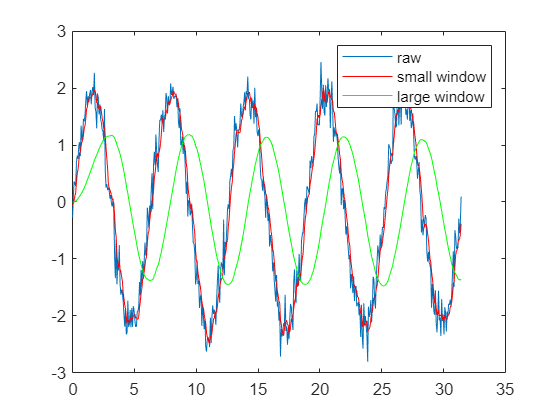

%create some fake data
x=linspace(0,10*pi,500);
y=2*sin(x);
%add some noise
y=y+0.25*(randn(size(y))-0.5);

figure
plot(x,y)
hold on

%small filter window
windowsize=5;
h=ones(1,windowsize)/windowsize; %this creates a vector of 'equal weighting coefficients'
ynew=filter(h,1,y); %see help entry on filter command to understand role of first two entries
plot(x,ynew,'r')

%big window
windowsize=50;
h=ones(1,windowsize)/windowsize;
ynew2=filter(h,1,y);
plot(x,ynew2,'g')
legend('raw','small window','large window')
hold off

note poor performance (over smoothing) and phase shift of the green line. Due to window not being centered. In other words, the filtering is based on the current point and the next N points.

#### filtfilt

There are zillions of other options in Matlab. Filtfilt is a function found in the signal processing toolbox. This function operates sort of like what we saw above, but it applies the filtering in BOTH directions. So, this should hopefully remove the phase shift we saw above. Let's try it.

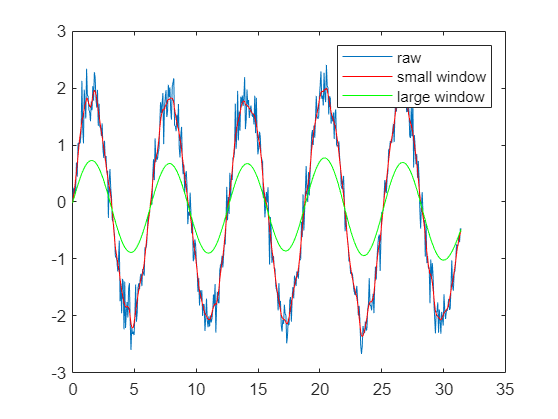

%create some fake data
x=linspace(0,10*pi,500);
y=2*sin(x);
%add some noise
y=y+0.25*(randn(size(y))-0.5);

figure
plot(x,y);
hold on

%small window
windowsize=5;
h=ones(1,windowsize)/windowsize;
ynew=filtfilt(h,1,y);
plot(x,ynew,'r')

%large window
windowsize=50;
h=ones(1,windowsize)/windowsize;
ynew2=filtfilt(h,1,y);
plot(x,ynew2,'g')
hold off

legend('raw','small window','large window')

NO SHIFT! Seems to be more filtering (heavily damped green line). Filter is applied forwards and then in reverse...so 'twice' the filtering and NO phase shift. See also medfilt1 (very easy to use).

#### Smooth

'smooth' is a great built-in matlab function for this...very easy to use, nice results.

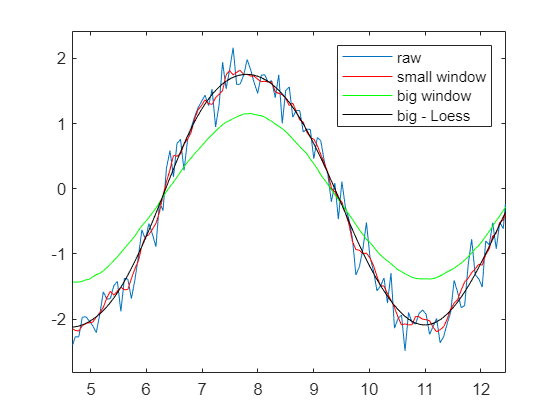

%create some fake data
x=linspace(0,10*pi,500);
y=2*sin(x);
%add some noise
y=y+0.25*(randn(size(y))-0.5);

figure
plot(x,y)
hold on

%small window
y2=smooth(y,5);
plot(x,y2,'r')

%large window
y3=smooth(y,50);
plot(x,y3,'g')  %Note that the output of this is centered...no phase shift.

%try one more thing...
y4=smooth(y,50,'rloess'); %locally estimated scatterplot smoothing
plot(x,y4,'k')
hold off
legend('raw','small window','big window','big - Loess')

Check out the loess performance!! Smooths out noise, but keeps signal! A local least squares regression is being performed. In essence, there is a 'kernel' of variable weights in this case. This approach is much more sophisiticated than the 'blunt tool' that we have been using above. More info [here](https://en.wikipedia.org/wiki/Local_regression), if you are interested.

## In-Class Exercise

Ok, let's try something fun. First, I want you to use your phone to make an audio recording. You can sing, you can say a single sentence. Whatever. Make it at least 5 seconds long. How do you do this?

- If you have an iPhone, use the 'voice memos' app.

- After stopping the recording, touch the circle at right with the three dots. 

- Touch the 'share' option and you can email it to yourself. If you are working on your own laptop, you can airdrop it. It should be an .m4a file.

- If you are an Android user, I have no idea, sorry.  :)

- If this does not work for you, no worries, you can use the supplied .m4a file in the class notes for this week.

Next, try to load the recording in Matlab. You can do this with something like

>> [y,fs]=audioread('recording.m4a');

y will be a vector containing the data (try to plot it!) and fs will tell you the sampling frequency (in Hz, or cycles per second...it should be a very high number). Your plot will look something like

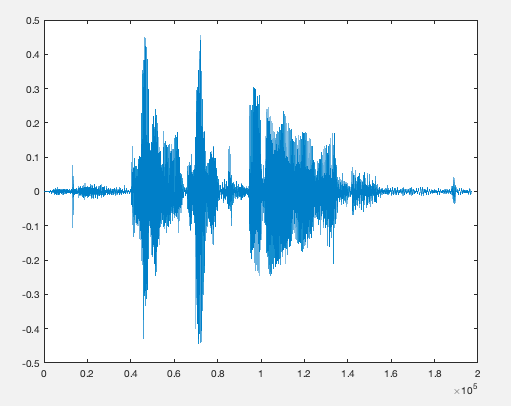

Next, try to play this recording. You can do this with something like

>> soundsc(y,fs)

Nice! Ok, so in my plot, the peak 'amplitudes' are like +/- 0.5 or so. And, this is a nice clean recording. So, let's mess with it. Let's add some noise! You could try something like:

>> y2 = y + (rand(size(y))*0.2)-.1;

In that, I am creating some random numbers between 0 and 0.2, and I then shift them to be between -0.1 and 0.1. Feel free to experiment with these numbers. Use 0.4 and 0.2 instead. After you do this, try

>> soundsc(y2,fs)

You SHOULD hear some really crackly version of the recording. This is a classic audio engineering problem. Noise, and how can we remove it from a recording.

Ok, so can you now figure out some simple ways to try and 'recover' the original recording? Play around with settings..how to smooth and how much to smooth?! Good luck.

#### Filtering out certain frequencies

So, up above, everything that we are doing is essentially smoothing out our data. All of the 'high frequency' oscillations are being removed. This is a common task since many instruments have inherent random noise in them and we would like to remove that noise and focus on the actual signal being measured.

Other types of filtering includes situations where we would like to screen out all behavior ABOVE a certain frequency. Or BELOW a certain frequency. Or INBETWEEN two frequencies. 

There are MANY options here. Chebyshv filters, Elliptic filters, and so on. You can go down a deep rabbit hole on signal processing and filtering. I would like to show you one example using a Butterworth filter. A Butterworth filter tends to have nice smooth results.

%create some fake data
t=linspace(0,10*pi,500);
y=2*sin(t);
%add some noise
y=y+0.25*(randn(size(y))-0.5);

T=t(2)-t(1);    %step size

Ok, so be sure you understand this. We 'sample' an observation with a time interval, or step size. It could be one second. It could be one minute, or an hour. It depends on the measurement. The INVERSE of the step size is the 'sampling rate'. This is in unis of Hertz (Hz), or 'cycles per second'. So, if your step size is 1 s, your sampling rate is 1 Hz. If your step size is 0.1 s, your sampling rate is 10 Hz, and so on.

samplerate=1/T; %this is in Hz, or cycles per second

Now, here is the most confusing part. We can 'filter' by choosing a frequency and then opting to screen out frequencies above or below that value. BUT, the frequency that you specify is NOT given in units of Hz. It is given as a percentage (0 - 1) of 1/2 the sampling rate. So, below, if Wn = 1, you are choosing as your 'cutoff' frequency 1/2 the sampling rate. If Wn = 0.5, you are choosing as your cutoff frequency 1/4 of the sampline rate.

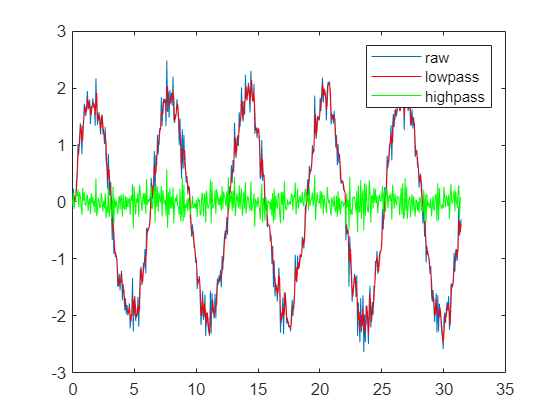

Wn=0.5; %percentage of 1/2 the sampling rate
[B,A]=butter(1,Wn); %this command simply constructs the filter coefficients. The DEFAULT is a low-pass filter.
yfilt=filter(B,A,y); %this command actually does the filtering
figure
plot(t,y); hold on
plot(t,yfilt,'r')

%high pass
[B,A]=butter(1,Wn,'high'); %the use of 'high' here does a high pass filter instead.
yfilt2=filter(B,A,y);
plot(t,yfilt2,'g')
legend('raw','lowpass','highpass')
hold off

The results are pretty neat. In the 'low pass' case (red line), you see that much of the high frequency noise is gone and we retain the sin wave. In the 'high pass' case (green line), the low-frequency sin wave has been screened out and we keep only the high frequency noise. You can also do cases where you have a 'band pass' (keep only the frequencies between two values) or a 'band stop' (block out the frequencies between two values.

#### More Butterworth Examples

Here I will show you a case with three dominant frequencies and how we can choose to filter out / keep only certain one.

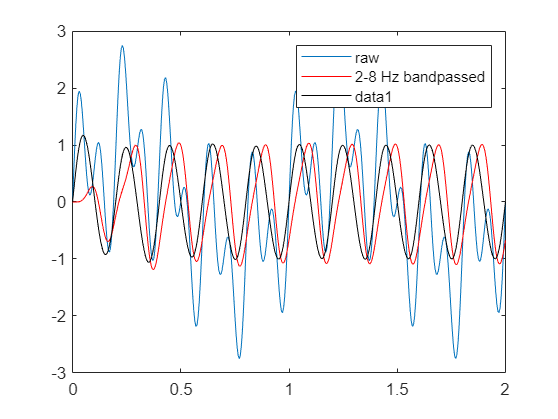

%specify three frequencies
f1=1;
f2=5;
f3=10;
%create a time vector
t=linspace(0,50,10000);  %sampling rate is 200 hz. 50 sec * 200 samples per sec = 10,000 samples.
y=sin(2*pi*f1*t)+sin(2*pi*f2*t)+sin(2*pi*f3*t); %create data with three frequencies present; 1, 5, and 10 Hz.
figure
plot(t,y)
axis([0 2 -3 3])
hold on

%sample rate is 200 hz. 1/2 the sample rate is 100 Hz. I will try to
%pass only frequencies in the band of 2 to 8 % of this 1/2 sample rate.
%Thus, we should keep the 5 Hz wave and screen out the other two.
[B,A]=butter(5,[0.02 0.08]);
yfilt=filter(B,A,y);
plot(t,yfilt,'r')
legend('raw','2-8 Hz bandpassed')

%Pretty good...can we do better?
yfilt2=filtfilt(B,A,y);
plot(t,yfilt2,'k')
hold off

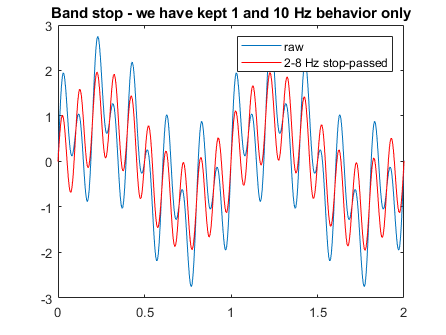

%using filtfilt reduces distortion and phase shift

%let's instead try a 'stop' filter with the same values. This should block
%out the 5 second wave. Cross your fingers.
[B,A]=butter(5,[0.02 0.08],'stop');
yfilt=filtfilt(B,A,y);
figure
plot(t,y)
hold on
plot(t,yfilt,'r')
axis([0 2 -3 3])
title('Band stop - we have kept 1 and 10 Hz behavior only')
legend('raw','2-8 Hz stop-passed')
hold off

## Block 4 - Two Dimensions

All of the concepts above can be applied to two-dimensional examples as well. For example, assume that you have a digital elevation model, or a DEM. This DEM may have 'noise' in it. LIDAR, for example, can produce fairly noisy datasets, with high-frequency fluctuations that are non-physical. So, we need to be able to filter these out, or to 'smooth' the dataset. And, as with the 1-D examples, we have to be careful to not be too heavy-handed with our smoothing. Let's just look at a simple example.

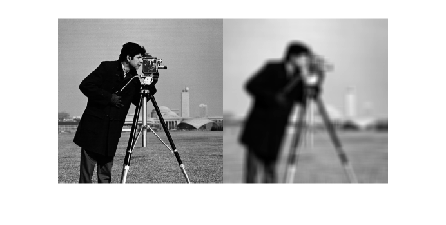

%I will just load in an existing photo from Matlab's image processing
%toolbox.
A = imread('cameraman.tif');

%Now, an image is just a checkerboard of 'pixels', like this:
%   value   |   value   |   value
%   -----       -----       -----
%   value   |   value   |   value
%   -----       -----       -----
%   value   |   value   |   value

%above, I am showing you a neighborhood of 9 cells. A very common filtering
%tool is a local mean / median filter. Here, the 'center' value gets
%replaces by the average of a 3x3 or a 5x5 or a 7x7 or whatever
%neighborhood surrounding it. Then, this process gets applied at every
%cell! This just smooths everything out.

%a little smoothing might be good; too much smoothing is bad, see below.
localMean = imboxfilt(A,11);
imshowpair(A,localMean,'montage')

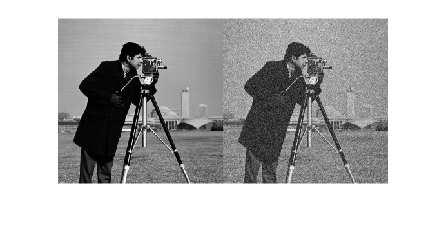

%Let's add some noise to this photo
noisypic=double(A)+randn(size(A))*20; %play with the multiplicative factor if you want
imshowpair(A,noisypic,'montage')

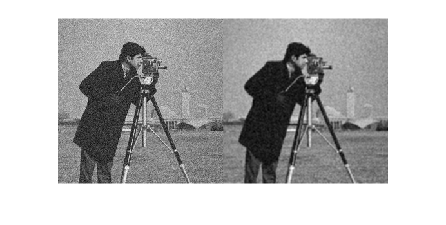

%Can we undo this noise??
filteredpic=imboxfilt(noisypic,3); %play with the multiplicative factor if you want
imshowpair(noisypic,filteredpic,'montage')

%The result does indeed remove a bit of the high frequency noise, but at
%the expense of blurring some of the detail in the image. So, we would need
%to use a more sophisticated tool (than a simple average filter). 

## Block 5 - FFT

This is 'extra credit' stuff here. Fast Fourier Transforms are valuable in that they convert from the time domain to the frequency domain. If you have a time series of data, a FFT will identify what frequencies dominate your signal. In the example below, I construct a signal made up of three waves. I then do an FFT on this signal and the second plot beautifully identifies the three frequencies contained in the signal.

%
% Example FFT
%

% Synthetic Data
 
fs = 8;
ts = 1/fs;
N = 100000;

t = ts*[0:N-1];
y = 2.0*sin(2*pi*t/50) + 1.0*sin(2*pi*t/15) + 0.5*sin(2*pi*t/5); %50s, 15s, and 5s waves

varTS = var(y,1); %compute variance directly from time series

 figure(1)
 plot(t,y);
 axis([0 100 -4 4])
 xlabel('time [s]'); ylabel('\eta [m]')
       
% Fast fouirer transfromation (FFT)

Y1 = fft(y);
a = abs(Y1)/N;
a = 2*(a(1:N/2));

df = 1/max(t);
f = df*[1:length(a)]';

Sf = a.^2./(2*df); %energy density spectrum

varSF = trapz(f,Sf); %compute variance

 figure(2)
 plot(f,Sf,'b'); hold on
 xlabel('f [Hz]'); ylabel('S_f [m^2-s]')
 xlim([0 1])